clc;
clear;
close all;

%% PARAMETERS
sim_time = 10;          % seconds
dt = 1e-4;              % time step
time = 0:dt:sim_time;

lambda = 500;           % arrival rate (packets/sec)
mu = 800;               % service rate (packets/sec)

packet_size = 1000;     % bits
buffer_size = 50;       % queue capacity

%% INITIALIZATION
queue = 0;
total_packets = 0;
dropped_packets = 0;
served_packets = 0;

delay = zeros(size(time));

%% SIMULATION LOOP
for i = 1:length(time)
    
    % Generate arrivals (Poisson using custom function)
    arrivals = poisson_gen(lambda * dt);
    total_packets = total_packets + arrivals;
    
    % Add to queue
    queue = queue + arrivals;
    
    % Drop if overflow
    if queue > buffer_size
        dropped_packets = dropped_packets + (queue - buffer_size);
        queue = buffer_size;
    end
    
    % Service packets
    served = min(queue, poisson_gen(mu * dt));
    queue = queue - served;
    served_packets = served_packets + served;
    
    % Delay approximation
    if served > 0
        delay(i) = queue / mu;
    end
end

%% METRICS
throughput = (served_packets * packet_size) / sim_time;
packet_loss = (dropped_packets / total_packets) * 100;
avg_delay = mean(delay) * 1000;  % ms
utilization = (served_packets / total_packets) * 100;

%% DISPLAY
fprintf('Throughput = %.2f bps\n', throughput);

Throughput = 505100.00 bps


fprintf('Packet Loss = %.2f %%\n', packet_loss);

Packet Loss = 0.00 %


fprintf('Average Delay = %.4f ms\n', avg_delay);

Average Delay = 0.1079 ms


fprintf('Utilization = %.2f %%\n', utilization);

Utilization = 99.84 %


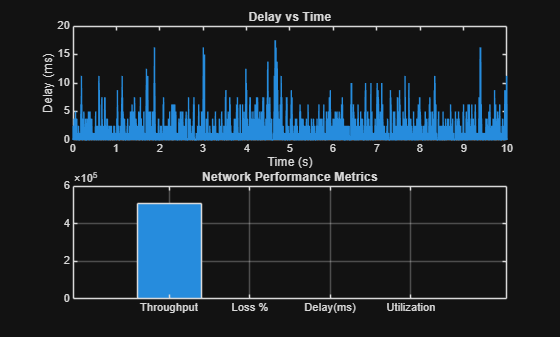


%% PLOTS
figure;

subplot(2,1,1);
plot(time, delay * 1000);
title('Delay vs Time');
xlabel('Time (s)');
ylabel('Delay (ms)');

subplot(2,1,2);
bar([throughput, packet_loss, avg_delay, utilization]);
set(gca, 'XTickLabel', {'Throughput','Loss %','Delay(ms)','Utilization'});
title('Network Performance Metrics');
grid on;


%% -------------------------------
%% CUSTOM POISSON GENERATOR
%% -------------------------------
function k = poisson_gen(lambda)
    L = exp(-lambda);
    p = 1;
    k = 0;
    
    while p > L
        k = k + 1;
        p = p * rand;
    end
    
    k = k - 1;
end